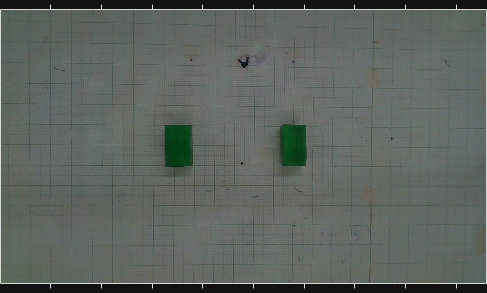

green = "green_cubes_Color.png";

[I_g, g_map] = imread(green); % TODO: Adaptive hist equalization
imshow(I_g)

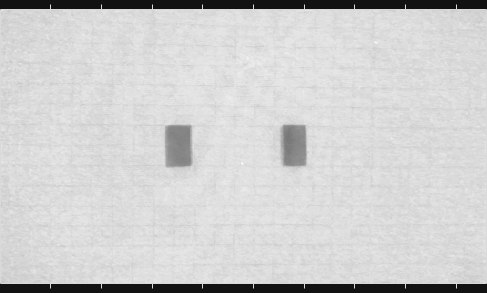

[rg,gg,bg] = imsplit(I_g);
imgLab = rgb2lab(I_g);
[L,a,b] = imsplit(imgLab);
imshow(a,[])

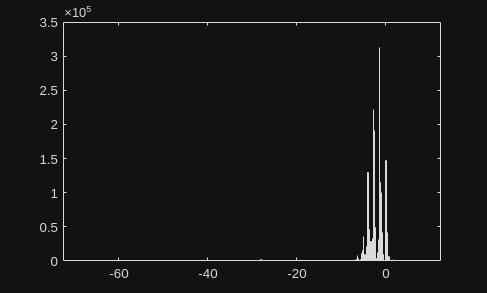

histogram(a)

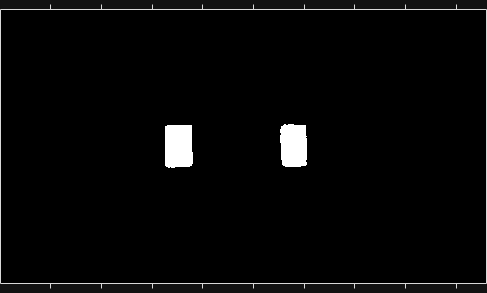


masked = a < -10;
imshow(masked);

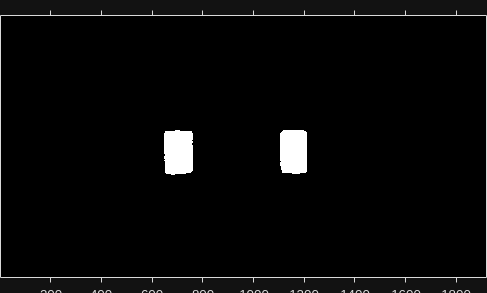

masked_med = wiener2(masked, [5,5]);
mask1 = bwareaopen(masked_med, 2000);
mask2 = imclearborder(mask1);
mask3 = imfill(mask2, "holes");
mask4 = imdilate(mask3, 1);
imshow(mask4)


% gmask = imbinarize(g)
% imshow(gmask)

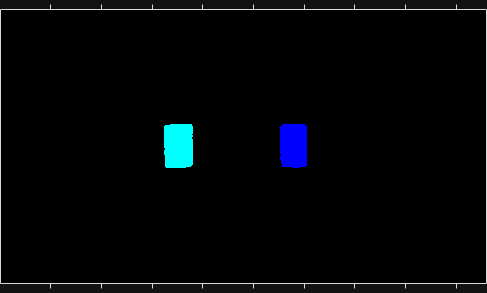

% Should filter between sizes for blocks??

boxCC = bwconncomp(mask4);
boxLabel = labelmatrix(boxCC);
boxRGB = label2rgb(boxLabel, "jet", "k", "shuffle");
imshow(boxRGB);

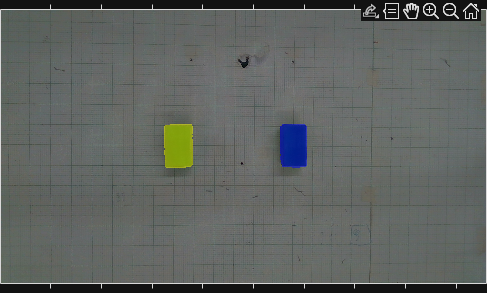


overlay = labeloverlay(I_g, boxLabel, 'Transparency', 0.5);
imshow(overlay)